# Práctica 4 - Trabajo sobre algoritmos y conceptos de navegación de robots.

- Enlace al prontuario solicitado al LLM: [https://chatgpt.com/share/6824fbee-74e4-8008-97c8-809d181e0f03](https://chatgpt.com/share/6824fbee-74e4-8008-97c8-809d181e0f03)

- Enlace al repositorio de github para acceder a los archivos de Matlab: 

##         Introducción

La planificación de movimiento es una de las tareas fundamentales en robótica móvil, especialmente cuando un robot debe desplazarse por un entorno complejo sin colisionar con obstáculos. Para resolver este problema, se combinan estrategias de creación de mapas con algoritmos de búsqueda que permiten hallar la mejor trayectoria desde un punto de partida hasta un punto destino.

En este trabajo vamos a aplicar lo aprendido durante el tema 4, comenzando por la generación de un mapa de carreteras mediante el algoritmo PRM (Probabilistic Roadmap) para, a continuación, aplicar diferentes algoritmos de búsqueda como A*, D* y Theta* sobre el grafo resultante. De esta forma, vamos a poder observar cómo se comportan estos métodos en cuanto a eficiencia y capacidad de adaptación.

Se va a plantear un entorno simulado con obstáculos, representado mediante un mapa bidimensional. El robot debe planificar un trayecto desde un punto inicial hasta un punto objetivo, evitando los obstáculos. 

Para ello:

- Primero vamos a construir un grafo utilizando el algoritmo PRM.

- A continuación, se aplicarán tres algoritmos de búsqueda: A* (algoritmo clásico con heurística admisible), D* (variante que permite la replanificación eficiente) y Theta* (mejora sobre A* que permite movimientos más naturales).

- Finalmente, se compararán los resultados en términos de eficiencia.

##         Descripción de los algoritmos

### 1. PRM (Probabilistic Roadmap)

Se encarga de crear un mapa con caminos seguros por donde puede ir el robot sin chocar con los diferentes obstáculos que pueda haber distribuidos por el entorno. El algoritmo sigue los siguientes pasos:

- Colocar puntos al azar sobre el mapa.

- Comprueba si entre dos puntos no hay ningún obstáculo y, si es así, los conecta.

Finalmente tendremos el grafo, un mapa de conexiones que se puede utilizar para buscar caminos entre el punto origen y el punto destino.

### 2. A*

Este algoritmo se encarga de buscar el mejor camino en el mapa generado. El algoritmo funciona:

- Comienza desde el punto inicio y, en cada paso, mira qué punto es mejor avanzar según: cuánto ha caminado ya, *g(n)*, y cuánto le queda por caminar (heurística), *h(n)*.

- Finalmente suma ambos: *f(n) = g(n) + h(n)* y, cuanto más pequeño, mejor.

### 3. D*

Este algoritmo es una versión dinámica del algoritmo A* ya que se encarga de recalcular una parte del camino si aparece un nuevo obstáculo o cambia el entorno. Se basa en:

- Planificación constante del camino desde el objetivo hacia el robot.

- Guardar partes del camino que ya ha calculado.

- Ante cualquier cambio, solo actualiza lo necesario, no empieza desde cero.

### 4. Theta*

El algoritmo sirve para encontrar caminos más naturales y suaves. Funciona de forma:

- Partiendo del algoritmo A* pero, con una diferencia, si puede ir de manera más rápida, procede a hacerlo. De esta forma, el robot hace menos giros y conduce de manera más fluida. 

##     Diseño del entorno 2D 

- Matriz de ocupación 25x25

- Relleno de las pareces externas

- Incluir obstáculos internos 

- Establecer punto inicial (2,2) y punto final (24,24)

- Visualizar el entorno con colores

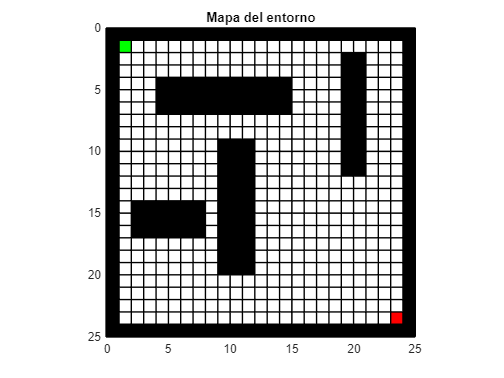

% Tamaño del entorno
rows = 25;
cols = 25;

% Inicializar mapa vacío (0 = libre, 1 = obstáculo)
map = zeros(rows, cols);

% Añadir paredes externas
map(1,:) = 1;
map(end,:) = 1;
map(:,1) = 1;
map(:,end) = 1;

% Añadir obstáculos rectangulares internos (ejemplo fijo)
map(5:7, 5:15) = 1;     % Obstáculo horizontal
map(10:20, 10:12) = 1;  % Obstáculo vertical
map(15:17, 3:8) = 1;    % Otro horizontal
map(3:12, 20:21) = 1;   % Otro vertical

% Definir posiciones de inicio y fin
start = [2, 2];
goal = [24, 24];

% Visualizar el mapa
figure;
hold on;
axis equal;
axis([0 cols 0 rows]);
set(gca, 'YDir','reverse');
title('Mapa del entorno');

% Dibujar mapa
for i = 1:rows
    for j = 1:cols
        if map(i,j) == 1
            fill([j-1 j j j-1], [i-1 i-1 i i], 'k'); % Obstáculo: negro
        else
            fill([j-1 j j j-1], [i-1 i-1 i i], 'w'); % Libre: blanco
        end
    end
end

% Pintar punto inicial
fill([start(2)-1 start(2) start(2) start(2)-1], [start(1)-1 start(1)-1 start(1) start(1)], 'g');

% Pintar punto final
fill([goal(2)-1 goal(2) goal(2) goal(2)-1], [goal(1)-1 goal(1)-1 goal(1) goal(1)], 'r');

hold off;

##     Diseño del robot

Con el uso de la función *drawRobot.m* vamos a diseñar un robot con:

- La posición del centro del eje trasero del robot 

- Una orientación

- Y un tamaño base

Esta función generará y dibujará un triángulo azul que representa al robot, con:

- Vértice A apuntando en la dirección del movimiento (orientación)

- Vértice B y C en la parte trasera 

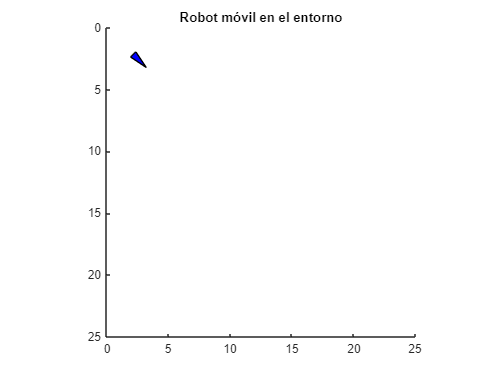

% Posición inicial del robot
x = 2.5;  % Centro del eje trasero en X (ajustado a coordenadas del mapa)
y = 2.5;  % Centro del eje trasero en Y
theta = pi/4;  % Orientación en radianes (45 grados)

% Dibujar entorno primero (asumiendo que ya está creado)
% Luego dibujar robot encima
figure;
axis equal;
axis([0 25 0 25]);
set(gca, 'YDir', 'reverse'); % Para alinear con la matriz de ocupación
hold on;

% Dibujar robot
drawRobot(x, y, theta, 'b');
title('Robot móvil en el entorno');
hold off;

##     Aplicación del algoritmo PRM

Vamos a construir un PRM para el entorno diseñado que nos genere los diferentes caminos libres de obstáculos que podrá recorrer el robot desde el punto inicial al punto final sin chocarse.

Para ello vamos a generar dos funciones:

- *buildPRM* para aplicar el algoritmo.

- *isCollisionFree* para asegurarnos que evita chocarse con los diferentes obstáculos del entorno.

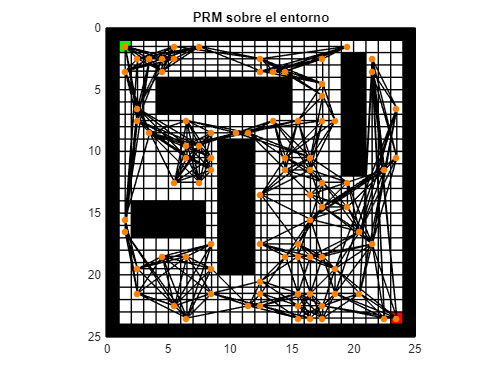

start_pos = [2.5, 2.5];
goal_pos = [23.5, 23.5];

figure;
hold on;
axis equal;
axis([0 25 0 25]);
set(gca, 'YDir', 'reverse');
title('PRM sobre el entorno');

% Dibujar mapa con obstáculos como antes
for i = 1:rows
    for j = 1:cols
        if map(i,j) == 1
            fill([j-1 j j j-1], [i-1 i-1 i i], 'k');
        else
            fill([j-1 j j j-1], [i-1 i-1 i i], 'w');
        end
    end
end

% Pintar inicio y fin
fill([1 2 2 1], [1 1 2 2], 'g'); % inicio (2,2)
fill([23 24 24 23], [23 23 24 24], 'r'); % destino (24,24)

% Construir y dibujar PRM
[nodes, edges] = buildPRM_fixed(map, 100, 10, start_pos, goal_pos);

El grafo que hemos obtenido al compilar el bloque anterior es el siguiente: 

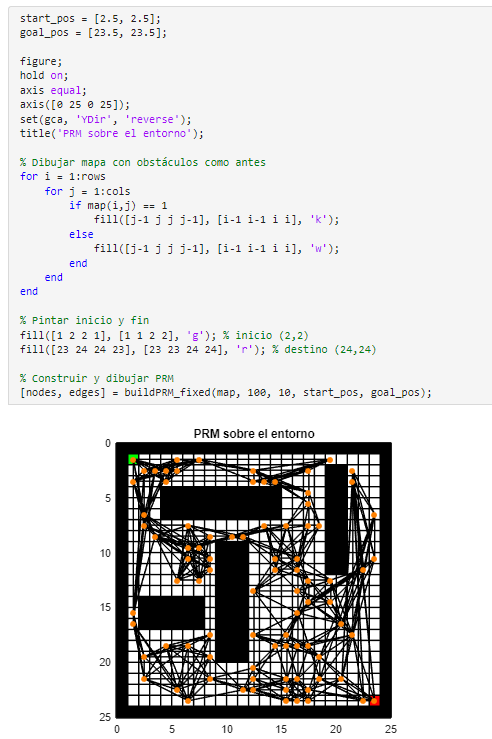

Para evitar perderlo por cerrar el programa, perder conexión o cualquier inconveniente dado que nos haga tener que recompilar el bloque y, por tanto, obtener un grafo distinto por el relanzamiento del algoritmo, he decidido guardarlo en el siguiente archivo:

%%%%% Guardamos el entorno con el grafo
save('entorno_con_prm.mat', 'map', 'nodes', 'edges', 'start_pos', 'goal_pos', 'rows', 'cols');

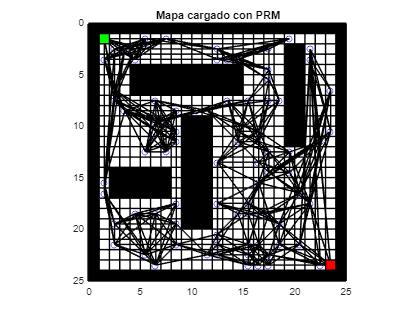

%%%%% Carga del entorno
load('entorno_con_prm.mat');

% Puedes volver a dibujar el entorno y el PRM así:
figure;
hold on;
axis equal;
axis([0 cols 0 rows]);
set(gca, 'YDir', 'reverse');
title('Mapa cargado con PRM');

% Dibujar el mapa
for i = 1:rows
    for j = 1:cols
        if map(i,j) == 1
            fill([j-1 j j j-1], [i-1 i-1 i i], 'k');
        else
            fill([j-1 j j j-1], [i-1 i-1 i i], 'w');
        end
    end
end

% Dibujar nodos
plot(nodes(:,1), nodes(:,2), 'bo');

% Dibujar aristas
for k = 1:size(edges,1)
    plot([nodes(edges(k,1),1), nodes(edges(k,2),1)], ...
         [nodes(edges(k,1),2), nodes(edges(k,2),2)], 'black');
end

% Dibujar inicio y destino
% Pintar punto inicial
fill([start(2)-1 start(2) start(2) start(2)-1], [start(1)-1 start(1)-1 start(1) start(1)], 'g');

% Pintar punto final
fill([goal(2)-1 goal(2) goal(2) goal(2)-1], [goal(1)-1 goal(1)-1 goal(1) goal(1)], 'r');

##     Aplicación del algoritmo A*

Una vez cargado el grafo, podemos aplicar el algoritmo A*, que sigue los siguientes pasos:

1.. Inicializa:

- *Open list*: nodos por explorar comenzando por el nodo inicial.

- *Closed list*: nodos ya explorados.

- *g*: vector de costes desde el inicio de cada nodo.

- *f*: vector de costes totales.

- *padre*: para reconstruir el camino.

2.. Mientras queden nodos en *open*:

- Selecciona el nodo *n* con menor *f(n)* en la *Open list*.

- Si *n* es el nodo objetivo, hemos terminado y se reconstruye el camino con *padre*.

- Mueve *n* a la *Closed list*.

- Para cada vecino *v* de *n*:

                -   Si *v* ya está en *Closed list*, lo ignoramos.

                -   Calcula *g_temp = g(n) + coste(n, v)*

                -   Si *v* no está en *Open list* o *g_temp < g(v)*:

                            ·   Actualiza *padre(v) = n*

*                            ·*   Actualiza *g(v)* y *f(v) = g(v) + h(v)*

*                            ·   *Añade *v* a *Open list *si no está

El código:

- Encuentra los índices de los nodos más cercanos a *start_pos* y *goal_pos*

- Aplica el algoritmo A* sobre el grafo *nodes-edges*

- Devuelve el camino óptimo como una lista de nodos

- Lo visualiza sobre el entorno

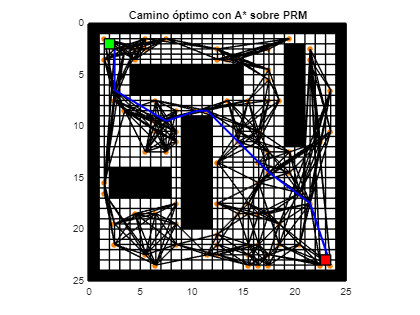

% Cargar el entorno
load('entorno_con_prm.mat');

% Encontrar nodos más cercanos a inicio y final
d_start = vecnorm(nodes - start_pos, 2, 2);
d_goal = vecnorm(nodes - goal_pos, 2, 2);
[~, start_idx] = min(d_start);
[~, goal_idx] = min(d_goal);

% Ejecutar A*
path_astar = astarPRM(nodes, edges, start_idx, goal_idx);

% Dibujar camino
figure;
hold on;
axis equal;
axis([0 cols 0 rows]);
set(gca, 'YDir', 'reverse');
title('Camino óptimo con A* sobre PRM');

% Redibuja entorno (como antes)
for i = 1:rows
    for j = 1:cols
        if map(i,j) == 1
            fill([j-1 j j j-1], [i-1 i-1 i i], 'k');
        else
            fill([j-1 j j j-1], [i-1 i-1 i i], 'w');
        end
    end
end

% Pintar nodos
scatter(nodes(:,1), nodes(:,2), 30, [1, 0.5, 0], 'filled');

% Pintar conexiones del grafo
for k = 1:size(edges,1)
    plot([nodes(edges(k,1),1), nodes(edges(k,2),1)], ...
         [nodes(edges(k,1),2), nodes(edges(k,2),2)], 'k-');
end

% Pintar el camino encontrado
for i = 1:(length(path_astar)-1)
    plot([nodes(path_astar(i),1), nodes(path_astar(i+1),1)], ...
         [nodes(path_astar(i),2), nodes(path_astar(i+1),2)], 'b-', 'LineWidth', 2);
end

% Pintar inicio y fin
fill([start_pos(1)-1 start_pos(1) start_pos(1) start_pos(1)-1], ...
     [start_pos(2)-1 start_pos(2)-1 start_pos(2) start_pos(2)], 'g');

fill([goal_pos(1)-1 goal_pos(1) goal_pos(1) goal_pos(1)-1], ...
     [goal_pos(2)-1 goal_pos(2)-1 goal_pos(2) goal_pos(2)], 'r');

hold off;

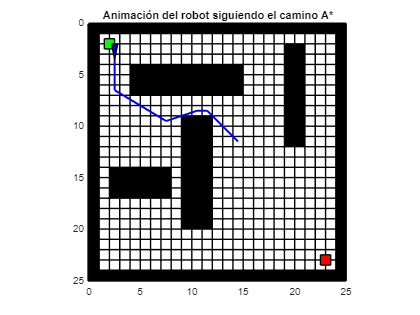

% Visualización del entorno
figure;
hold on;
axis equal;
axis([0 cols 0 rows]);
set(gca, 'YDir', 'reverse');
title('Animación del robot siguiendo el camino A*');

% Dibujar entorno como antes
for i = 1:rows
    for j = 1:cols
        if map(i,j) == 1
            fill([j-1 j j j-1], [i-1 i-1 i i], 'k');
        else
            fill([j-1 j j j-1], [i-1 i-1 i i], 'w');
        end
    end
end

% Dibujar camino óptimo
for i = 1:(length(path)-1)
    plot([nodes(path_astar(i),1), nodes(path_astar(i+1),1)], ...
         [nodes(path_astar(i),2), nodes(path_astar(i+1),2)], 'b-', 'LineWidth', 2);
end

% Dibujar puntos de inicio y final
fill([start_pos(1)-1 start_pos(1) start_pos(1) start_pos(1)-1], ...
     [start_pos(2)-1 start_pos(2)-1 start_pos(2) start_pos(2)], 'g');

fill([goal_pos(1)-1 goal_pos(1) goal_pos(1) goal_pos(1)-1], ...
     [goal_pos(2)-1 goal_pos(2)-1 goal_pos(2) goal_pos(2)], 'r');

% Animar robot sobre el camino
for i = 1:(length(path_astar)-1)
    p1 = nodes(path_astar(i), :);
    p2 = nodes(path_astar(i+1), :);
    theta = atan2(p2(2) - p1(2), p2(1) - p1(1));

    % Mostrar robot
    drawRobot(p1(1), p1(2), theta, 'b');

    pause(0.1); % velocidad de animación
    if i < length(path)-1
        cla; % borrar figura para siguiente frame
        % Redibujar fondo
        for ii = 1:rows
            for jj = 1:cols
                if map(ii,jj) == 1
                    fill([jj-1 jj jj jj-1], [ii-1 ii-1 ii ii], 'k');
                else
                    fill([jj-1 jj jj jj-1], [ii-1 ii-1 ii ii], 'w');
                end
            end
        end
        % Redibujar camino
        for k = 1:(length(path)-1)
            plot([nodes(path_astar(k),1), nodes(path_astar(k+1),1)], ...
                 [nodes(path_astar(k),2), nodes(path_astar(k+1),2)], 'b-', 'LineWidth', 2);
        end
        % Redibujar inicio y final
        fill([start_pos(1)-1 start_pos(1) start_pos(1) start_pos(1)-1], ...
             [start_pos(2)-1 start_pos(2)-1 start_pos(2) start_pos(2)], 'g');
        fill([goal_pos(1)-1 goal_pos(1) goal_pos(1) goal_pos(1)-1], ...
             [goal_pos(2)-1 goal_pos(2)-1 goal_pos(2) goal_pos(2)], 'r');
    end
end

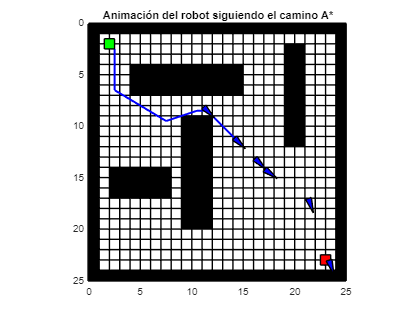

% Última posición (meta)
drawRobot(nodes(path_astar(end),1), nodes(path_astar(end),2), theta, 'b');

##     Implementación del algoritmo Theta*

Para implementar este algoritmo:

- Se parte del mismo esquema que A*

- En vez de siempre asignar como padre de un nodo *n* al nodo actual *curr*, se intenta conectar *n* directamente con el padre de *curr*, si hay línea de visión libre

- La función *g(n)* se actualiza en función de esa conexión directa

- Esto reduce esquina innecesarias y evita caminos en 'zig-zag'

load('entorno_con_prm.mat'); % map, nodes, edges, start_pos, goal_pos

% Encontrar índices del nodo más cercano a inicio y fin
[~, start_idx] = min(vecnorm(nodes - start_pos, 2, 2));
[~, goal_idx] = min(vecnorm(nodes - goal_pos, 2, 2));

% Ejecutar Theta*
path_theta = thetaStarPRM(nodes, edges, start_idx, goal_idx, map);

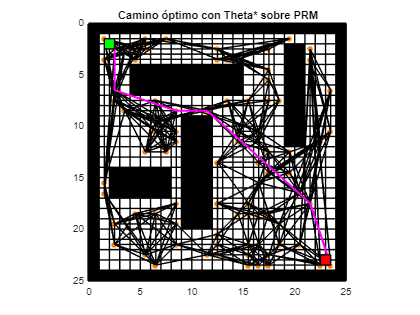

% Visualizar el camino de Theta*
figure;
hold on;
axis equal;
axis([0 cols 0 rows]);
set(gca, 'YDir', 'reverse');
title('Camino óptimo con Theta* sobre PRM');

% Dibujar el mapa
for i = 1:rows
    for j = 1:cols
        if map(i,j) == 1
            fill([j-1 j j j-1], [i-1 i-1 i i], 'k'); % Obstáculo
        else
            fill([j-1 j j j-1], [i-1 i-1 i i], 'w'); % Libre
        end
    end
end

% Dibujar nodos PRM
scatter(nodes(:,1), nodes(:,2), 30, [1, 0.5, 0], 'filled');

% Dibujar aristas
for k = 1:size(edges,1)
    plot([nodes(edges(k,1),1), nodes(edges(k,2),1)], ...
         [nodes(edges(k,1),2), nodes(edges(k,2),2)], 'k-');
end

% Dibujar camino encontrado por Theta*
for i = 1:(length(path)-1)
    plot([nodes(path_theta(i),1), nodes(path_theta(i+1),1)], ...
         [nodes(path_theta(i),2), nodes(path_theta(i+1),2)], 'm-', 'LineWidth', 2); % color magenta para Theta*
end

% Dibujar inicio y fin
fill([start_pos(1)-1 start_pos(1) start_pos(1) start_pos(1)-1], ...
     [start_pos(2)-1 start_pos(2)-1 start_pos(2) start_pos(2)], 'g');
fill([goal_pos(1)-1 goal_pos(1) goal_pos(1) goal_pos(1)-1], ...
     [goal_pos(2)-1 goal_pos(2)-1 goal_pos(2) goal_pos(2)], 'r');

hold off;

Podemos ver cómo se ha suavizado el camino que ya obtuvimos con el algoritmo A*.

##     Comparación entre lo obtenido con los algoritmos A* y Theta*

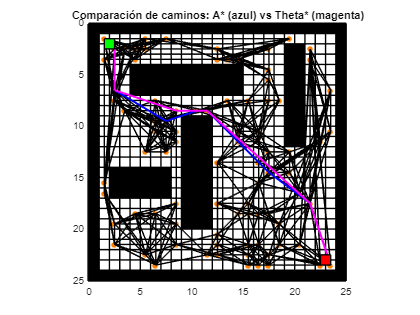

figure;
hold on;
axis equal;
axis([0 cols 0 rows]);
set(gca, 'YDir', 'reverse');
title('Comparación de caminos: A* (azul) vs Theta* (magenta)');

% Dibujar mapa con obstáculos
for i = 1:rows
    for j = 1:cols
        if map(i,j) == 1
            fill([j-1 j j j-1], [i-1 i-1 i i], 'k'); % Obstáculo
        else
            fill([j-1 j j j-1], [i-1 i-1 i i], 'w'); % Libre
        end
    end
end

% Dibujar nodos PRM
scatter(nodes(:,1), nodes(:,2), 30, [1, 0.5, 0], 'filled');

% Dibujar aristas del PRM
for k = 1:size(edges,1)
    plot([nodes(edges(k,1),1), nodes(edges(k,2),1)], ...
         [nodes(edges(k,1),2), nodes(edges(k,2),2)], 'k-');
end

% Dibujar camino A* (azul)
for i = 1:(length(path_astar)-1)
    plot([nodes(path_astar(i),1), nodes(path_astar(i+1),1)], ...
         [nodes(path_astar(i),2), nodes(path_astar(i+1),2)], 'b-', 'LineWidth', 2);
end

% Dibujar camino Theta* (magenta)
for i = 1:(length(path_theta)-1)
    plot([nodes(path_theta(i),1), nodes(path_theta(i+1),1)], ...
         [nodes(path_theta(i),2), nodes(path_theta(i+1),2)], 'm-', 'LineWidth', 2);
end

% Dibujar inicio y fin
fill([start_pos(1)-1 start_pos(1) start_pos(1) start_pos(1)-1], ...
     [start_pos(2)-1 start_pos(2)-1 start_pos(2) start_pos(2)], 'g');
fill([goal_pos(1)-1 goal_pos(1) goal_pos(1) goal_pos(1)-1], ...
     [goal_pos(2)-1 goal_pos(2)-1 goal_pos(2) goal_pos(2)], 'r');

hold off;

En este gráfico en el que comparamos ambos caminos, podemos observar cómo, en color azul, tenemos el camino obtenido con el algoritmo A* y, en color magenta, el camino obtenido con el algoritmo Theta* y, efectivamente, vemos como el camino obtenido con el algoritmo Theta* esta más suavizado que el del algoritmo A* que tiene un pico muy forzado cerca de las casillas (10,8).

Movimiento del robot a lo largo del camino obtenido con el algoritmo Theta*:

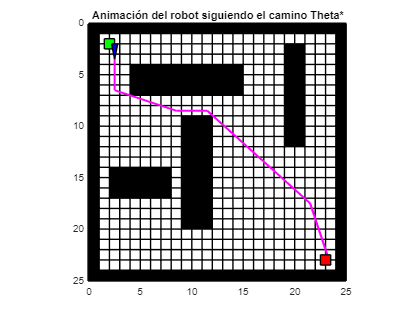

figure;
hold on;
axis equal;
axis([0 cols 0 rows]);
set(gca, 'YDir', 'reverse');
title('Animación del robot siguiendo el camino Theta*');

% Dibujar mapa inicial
for i = 1:rows
    for j = 1:cols
        if map(i,j) == 1
            fill([j-1 j j j-1], [i-1 i-1 i i], 'k'); % Obstáculo
        else
            fill([j-1 j j j-1], [i-1 i-1 i i], 'w'); % Libre
        end
    end
end

% Dibujar camino de Theta*
for i = 1:(length(path_theta)-1)
    plot([nodes(path_theta(i),1), nodes(path_theta(i+1),1)], ...
         [nodes(path_theta(i),2), nodes(path_theta(i+1),2)], 'm-', 'LineWidth', 2);
end

% Dibujar puntos de inicio y fin
fill([start_pos(1)-1 start_pos(1) start_pos(1) start_pos(1)-1], ...
     [start_pos(2)-1 start_pos(2)-1 start_pos(2) start_pos(2)], 'g');
fill([goal_pos(1)-1 goal_pos(1) goal_pos(1) goal_pos(1)-1], ...
     [goal_pos(2)-1 goal_pos(2)-1 goal_pos(2) goal_pos(2)], 'r');

% Animar el robot paso a paso
for i = 1:(length(path_theta)-1)
    p1 = nodes(path_theta(i), :);
    p2 = nodes(path_theta(i+1), :);
    theta = atan2(p2(2) - p1(2), p2(1) - p1(1));

    % Dibujar robot (triángulo azul)
    drawRobot(p1(1), p1(2), theta, 'b');
    pause(0.1);

    % Borrar frame anterior (excepto en el último)
    if i < length(path_theta)-1
        cla;

        % Redibujar fondo
        for ii = 1:rows
            for jj = 1:cols
                if map(ii,jj) == 1
                    fill([jj-1 jj jj jj-1], [ii-1 ii-1 ii ii], 'k');
                else
                    fill([jj-1 jj jj jj-1], [ii-1 ii-1 ii ii], 'w');
                end
            end
        end

        % Redibujar camino
        for k = 1:(length(path_theta)-1)
            plot([nodes(path_theta(k),1), nodes(path_theta(k+1),1)], ...
                 [nodes(path_theta(k),2), nodes(path_theta(k+1),2)], 'm-', 'LineWidth', 2);
        end

        % Redibujar inicio y fin
        fill([start_pos(1)-1 start_pos(1) start_pos(1) start_pos(1)-1], ...
             [start_pos(2)-1 start_pos(2)-1 start_pos(2) start_pos(2)], 'g');
        fill([goal_pos(1)-1 goal_pos(1) goal_pos(1) goal_pos(1)-1], ...
             [goal_pos(2)-1 goal_pos(2)-1 goal_pos(2) goal_pos(2)], 'r');
    end
end

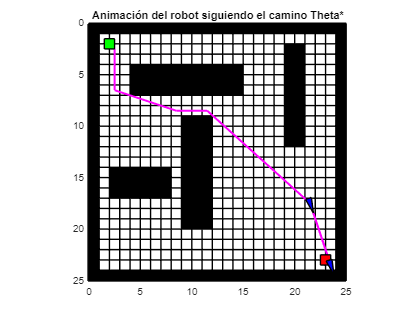

% Dibuja robot en la posición final
drawRobot(nodes(path_theta(end),1), nodes(path_theta(end),2), theta, 'b');

##     Cierre de la práctica

El tiempo empleado en la realización de esta práctica ha sido de unas 2 horas y media.

Durante el desarrollo de la práctica, el principal reto fue la implementación correcta del algoritmo PRM, concretamente en verificar que las conexiones entre nodos no atravesaran los obstáculos. El problema estuvo en la función *isCollisionesFree* que debía inspeccionar el recorrido punto a punto antes de aceptar la conexión para evitar que esta atraviese un obstáculo. 

Sin solucionar este problema, aplicar posteriormente los algoritmos de búsqueda habría causado problemas. 

Otro aspecto que presento alguna difultad fue la animación del robot moviéndose a lo largo del camino. Hay que estar muy atento para ver cómo el robot pasa por todos los nodos del recorrido antes de que termine la simulación. Y, por eso, hemos representado una imagen con el robot en la posición de inicio y otra con el robot en la posición final. 